## Feature extraction tests

clc;
close all;
clear variables;

### Loading files

input_file_subfolder = 'data\preprocessed\binarized';
intput_file_expension = 'bmp';

input_files = dir(input_file_subfolder + "/" +  "*." + intput_file_expension)

input_files = 600×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


### Example file

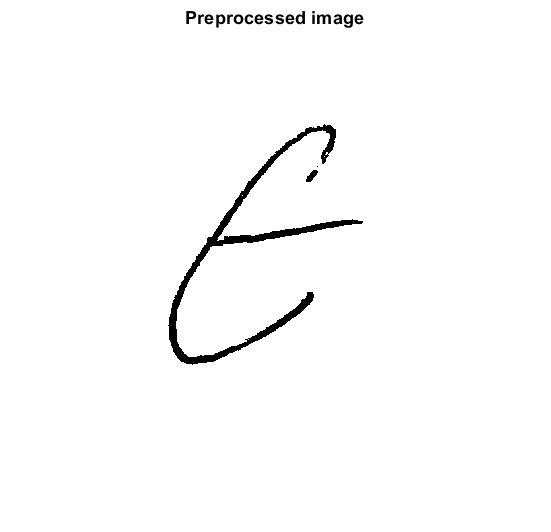

input_file = input_files(121);
file_path = input_file.folder + "\" + input_file.name;
img = imread(file_path);
figure()
imshow(img)
title('Preprocessed image')

### Extraction methods

#### Histogram of oriented gradients (HOG) 

[featureVector, hogVisualization] = extractHOGFeatures(img);
size(featureVector)

ans =            1       80784


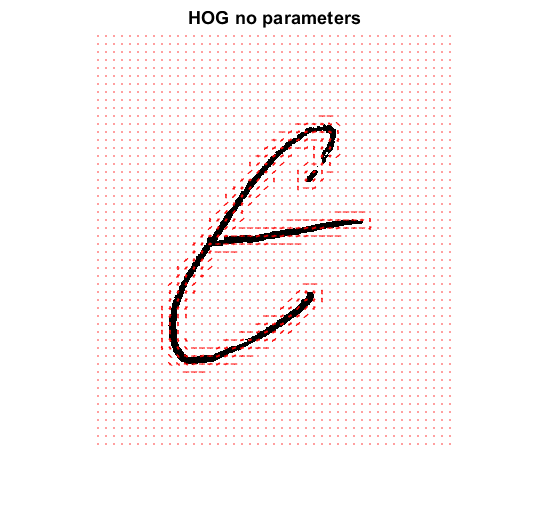

figure;
imshow(img); 
hold on;
plot(hogVisualization, 'Color', 'Red');
title("HOG no parameters")

Cell size

cell_size = 16;
[featureVector, hogVisualization] = extractHOGFeatures(img, 'CellSize',[cell_size cell_size]);
size(featureVector)

ans =            1       18900


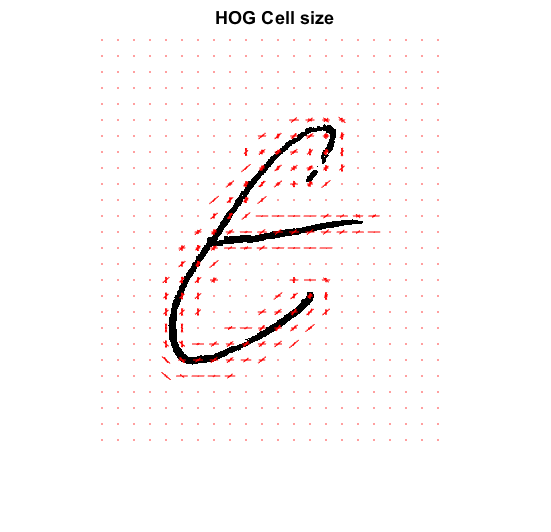

figure;
imshow(img); 
hold on;
plot(hogVisualization, 'Color', 'Red');
title("HOG Cell size")

num_bins = 3;
[featureVector, hogVisualization] = extractHOGFeatures(img, 'CellSize',[cell_size cell_size], 'NumBins',num_bins);
size(featureVector)

ans =            1        6300


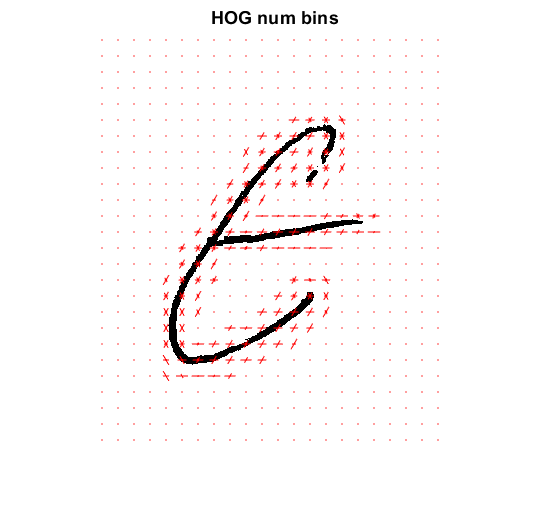

figure;
imshow(img); 
hold on;
plot(hogVisualization, 'Color', 'Red');
title("HOG num bins")

cell_size = 16;
[featureVector, hogVisualization] = extractHOGFeatures(img, 'CellSize',[cell_size cell_size], "UseSignedOrientation",true);
size(featureVector)

ans =            1       18900


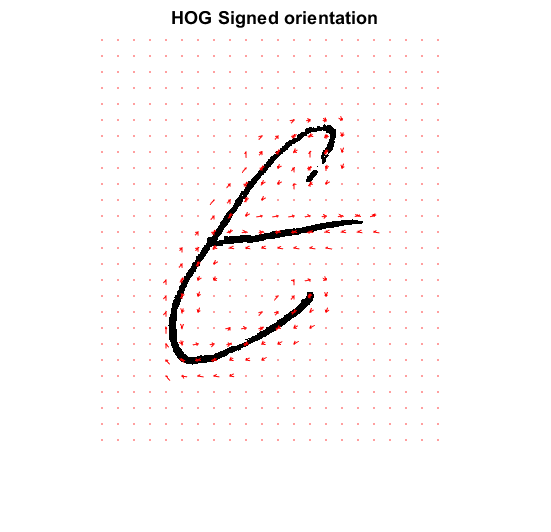

figure;
imshow(img); 
hold on;
plot(hogVisualization, 'Color', 'Red');
title("HOG Signed orientation")

Fast features - Strongest corners

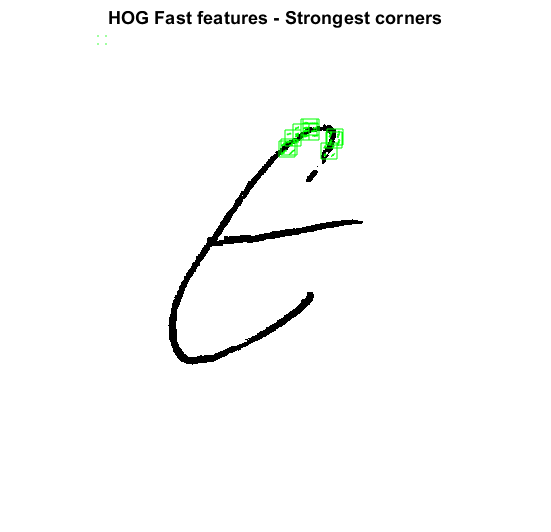

corners   = detectFASTFeatures(img);
strongest = selectStrongest(corners, 10);

[hog2, validPoints, ptVis] = extractHOGFeatures(img, strongest);

figure;
imshow(img);
hold on;
plot(ptVis,'Color','green');
title("HOG Fast features - Strongest corners")

% TODO dimensionality reduction

#### Harris detector

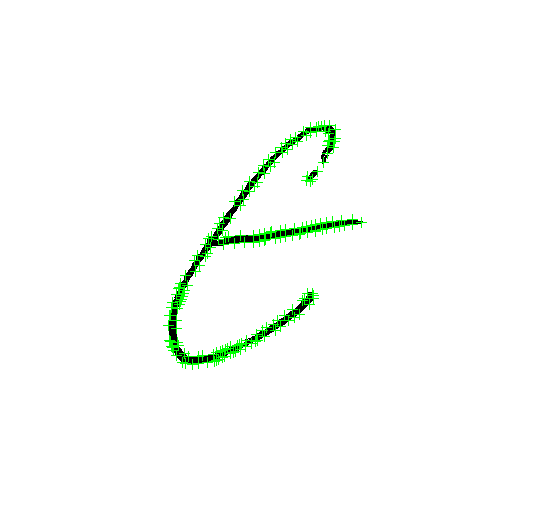

corners = detectHarrisFeatures(img);
[features, valid_corners] = extractFeatures(img, corners);
figure; imshow(img); hold on
plot(valid_corners);

#### Surf

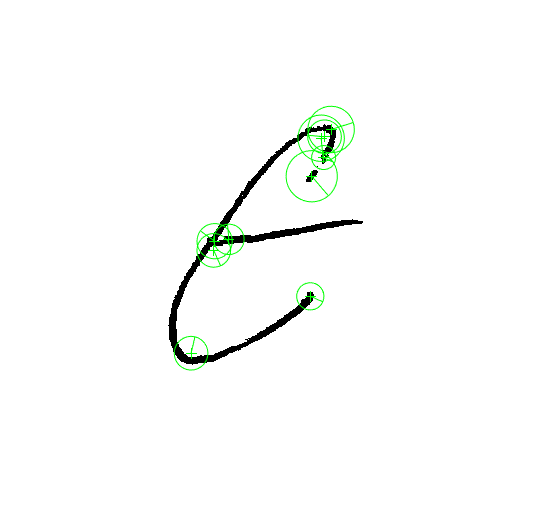

points = detectSURFFeatures(img);
[features, valid_points] = extractFeatures(img, points);
figure; imshow(img); hold on;
    plot(valid_points.selectStrongest(10),'showOrientation',true);

#### MSER

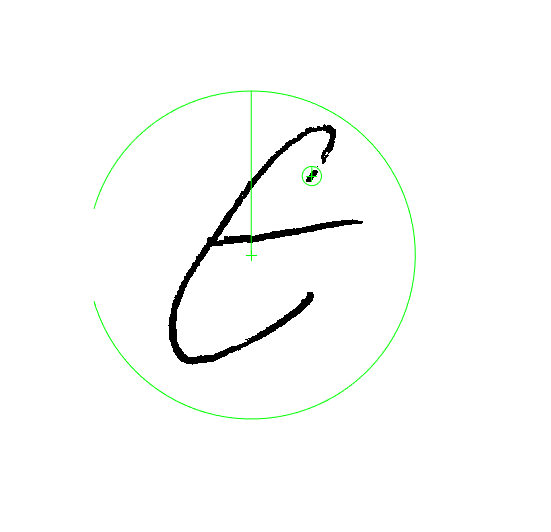

regions = detectMSERFeatures(img);
[features, valid_points] = extractFeatures(img, regions, 'Upright',true);
figure; imshow(img); hold on;
plot(valid_points,'showOrientation',true);